% cleaning
clc
clear

% importing data
df1=readtable("..\data\experimental-data-1.csv")

df1 = 6×4 table
    dimension    value    uncertainty      uom  
    _________    _____    ___________    _______

     {'d1'}       98           1         {'CMT'}
     {'d2'}       90           1         {'CMT'}
     {'d3'}       80           1         {'CMT'}
     {'d4'}       70           1         {'CMT'}
     {'d5'}       60           1         {'CMT'}
     {'d6'}       55           1         {'CMT'}


df2=readtable("..\data\experimental-data-2.csv")

df2 = 601×5 table
    event    distance    time    uncertainty      uom  
    _____    ________    ____    ___________    _______

      1       {'d1'}     819          1         {'C26'}
      2       {'d1'}     799          1         {'C26'}
      3       {'d1'}     818          1         {'C26'}
      4       {'d1'}     819          1         {'C26'}
      5       {'d1'}     815          1         {'C26'}
      6       {'d1'}     817          1         {'C26'}
      7       {'d1'}     818          1         {'C26'}
      8       {'d1'}     798          1         {'C26'}
      9       {'d1'}     819          1         {'C26'}
     10       {'d1'}     819          1         {'C26'}
     11       {'d1'}     819          1         {'C26'}
     12       {'d1'}     817          1         {'C26'}
     13       {'d1'}     81

tools=readtable("..\data\tools.csv")

tools = 2×3 table
             tool             uncertainty      uom  
    ______________________    ___________    _______

    {'sensore prossimità'}       0.001       {'SEC'}
    {'asta graduata'     }        0.01       {'MTR'}




% unique distance
d=unique(df2.distance);
ld=length(d);

% creating empty array
tm=zeros(ld,1);     % tempi medi
dtm=zeros(ld,1);    % deviazione standard tempi

% multiply *2
for i=1:height(df2)
    df2.time(i)=df2.time(i)*2;
end


% calculating mean t in s
for i=1:ld
    tm(i)=mean(table2array(df2(df2.distance==string(d(i)),"time"))./1000);
    dtm(i)=std(table2array(df2(df2.distance==string(d(i)),"time"))./1000);
end

cat(2,tm,dtm)

ans =     1.6275    0.0165
    1.5712    0.0192
    1.5604    0.0123
    1.5974    0.0105
    2.0203    0.0200
    3.1408    0.0235


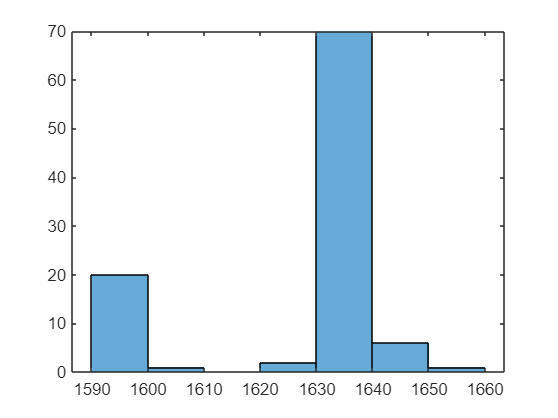


% histogram

histogram(table2array(df2(df2.distance==string(d(1)),"time")))

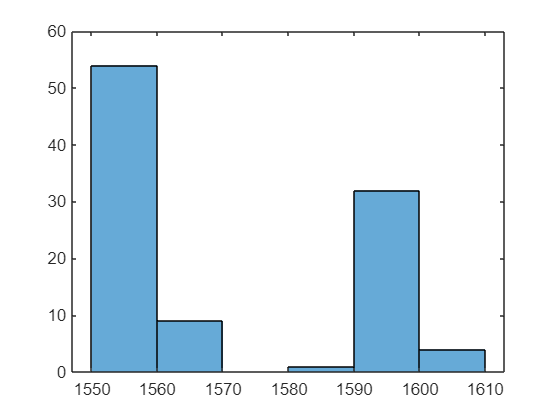

histogram(table2array(df2(df2.distance==string(d(2)),"time")))

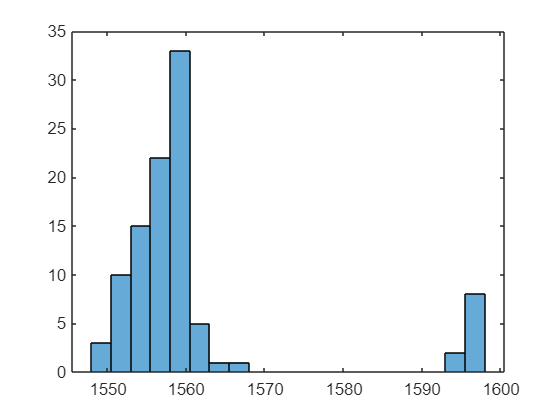

histogram(table2array(df2(df2.distance==string(d(3)),"time")),20)

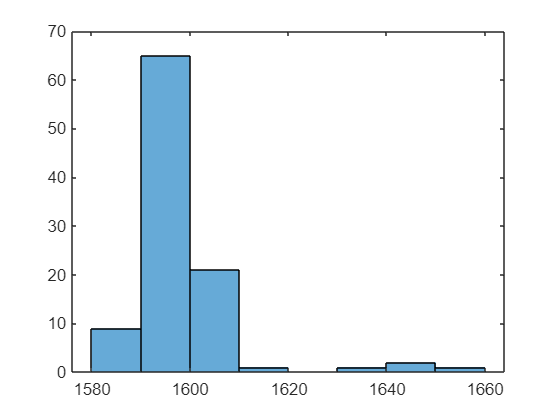

histogram(table2array(df2(df2.distance==string(d(4)),"time")))

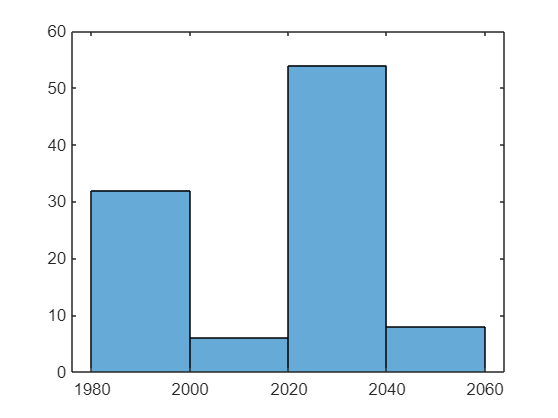

histogram(table2array(df2(df2.distance==string(d(5)),"time")))

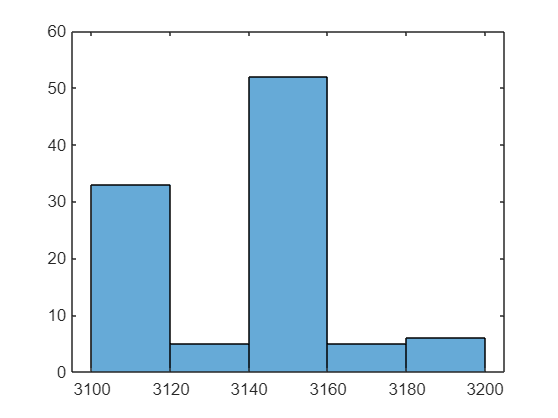

histogram(table2array(df2(df2.distance==string(d(6)),"time")))



% df2(df2.distance=="d1","time") % sostituire "d1" con gli elementi degli array
% mean(table2array(df2(df2.distance=="d1","time")))

% exporting csv
% writetable(array2table(namearray,'VariableNames',{'acceleration','uncertainty','uom','relative_error'}),'..\data\output-data-1.csv','Delimiter',',','Encoding','UTF-8')

% exporting img
% saveas(nameplot,'..\img\filename.png');

% exporting mlx2m
mlxloc = fullfile(pwd,'livescript.mlx');
fileout = 'script.m';
matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);